# Problem 1.10 

## Introduction

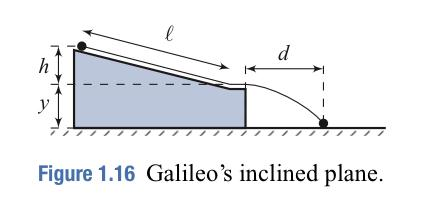

Students participating in Rice University’s Galileo Project set out to carefully reproduce some of Galileo’s classic experiments. One was the study of projectile motion using an inclined plane, in which a ball accelerates down a plane inclined at a certain angle then rolls in the horizontal direction with uniform motion for a short while until falling off the edge of a table, as shown in Fig. 1.16. The distance the ball rolled along the inclined plane, *l* in feet, and the distance from the end of the table to the landing site of the ball, *d* in inches, were recorded. Some of their data, five trials at two different angles, is reproduced in Table 1.2. Use MATLAB to plot and visualize the data. Fit simple equations, e.g. linear, quadratic, etc., to the data to relate the fall height, *h*, to the horizontal travel distance, *d*, given in Table 1.2. Justify your choice of equations and comment on the quality of the fit obtained in each case. Estimate using the given data the vertical distance *y*. Can you also estimate gravity?

## Programming

### Load and visualise data

The IV data corresponds to the horizontal distances travelled in inches. 

#### Ramp distance at 13.4 degrees

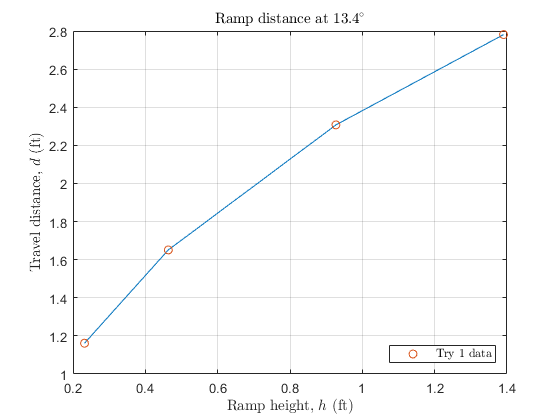

%% Load P1.10 Table 1.2 data
% Angle of inclined plane (degrees)
angle = 13.4;
% Travel distance d in inches converted to feet
DV1 = [13+(15/16); 19+(13/16); + 27+(11/16); 33+(3/8)] ./ 12;
DV2 = [13+(7/8); 19+(13/16); + 27+(3/4); 33+(5/16)] ./ 12;
DV3 = [14+(1/16); 19+(13/16); 27+(3/4); 33+(3/16)] ./ 12;
DV4 = [14; 19+(3/4); 27+(9/16); 33+(7/16)] ./12 ;
DV5 = [13+(15/16); 19+(3/4); 27+(9/16); 33+(5/8)] ./ 12;
% Ramp length l (ft) converted to vertical ramp height h
IV = [1; 2; 4; 6] .* sin(angle*(pi/180));


% Plot the first try
figure;
plot(IV, DV1);
hold on;
scatter(IV, DV1);
grid on;
title("Ramp distance at ${13.4}^\circ$", "interpreter", "latex");
legend("","$\textrm{Try 1 data}$", "interpreter", "latex",  location="southeast");
ylabel("Travel distance, $d$ (ft)", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");

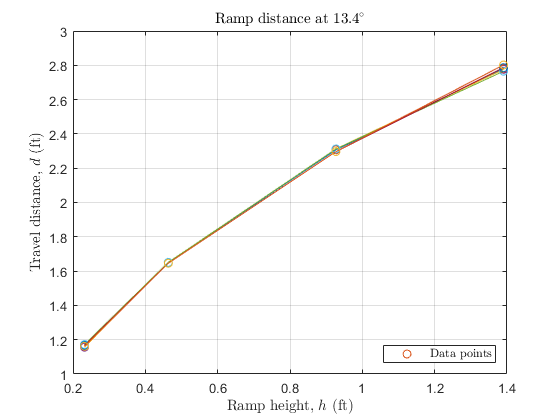



% Plot all five tries
figure;
for i = 1:5
    f = strcat('DV', num2str(i));
    plot(IV, eval(f));
    grid on;
    hold on;
    scatter(IV, eval(f));
end
legend("","$\textrm{Data points}$", "interpreter", "latex",  location="southeast");
title("Ramp distance at ${13.4}^\circ$", "interpreter", "latex");
ylabel("Travel distance, $d$ (ft)", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");

### Fitting simple equations

We will use MATLAB functions to perform a linear least-squares fit and inverse trigonometric fit.

#### Linear least-squares fit

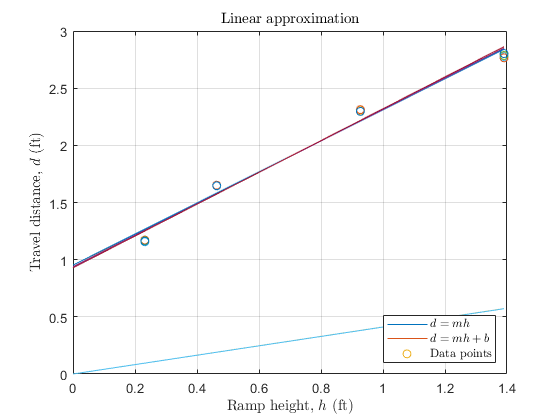

% Store each slope estimate in an array
ms = zeros(size(DV1'));

% Using the matrix right division operator
for i = 1:5
    f = strcat('DV', num2str(i));
    ms(1, i) = round(eval(f) \ IV, 5);
end

% Store parameters alpha, beta
linear_params = zeros(length(IV), 2);

% Using the fit function
for i = 1:5
    f = strcat('DV', num2str(i));
    ft = fit(IV, eval(f), 'poly1');
    % p1 is the slope
    linear_params(i, 1) = ft.p1;
    % p2 is the y-intercept
    linear_params(i, 2) = ft.p2;
end

% Plotting the linear models
figure;
h = linspace(0, max(IV), 30);
for i = 1:5
    % Plotting the left matrix divide operator curve
    d1 = ms(i) * h;
    plot(h, d1);
    grid on;
    hold on;
    % Plotting the fit function curve
    alpha = linear_params(i, 1);
    beta = linear_params(i, 2);
    d2 = alpha*h + beta;
    plot(h, d2);
    hold on;
    % Plotting the data points
    f = strcat('DV', num2str(i));
    scatter(IV, eval(f));
    hold on;
end
legend("$d = mh$", "$d=mh+b$", "$\textrm{Data points}$", "interpreter", "latex",  location="southeast");
title("Linear approximation", "interpreter", "latex");
ylabel("Travel distance, $d$ (ft)", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");

#### Inverse trigonometric fit

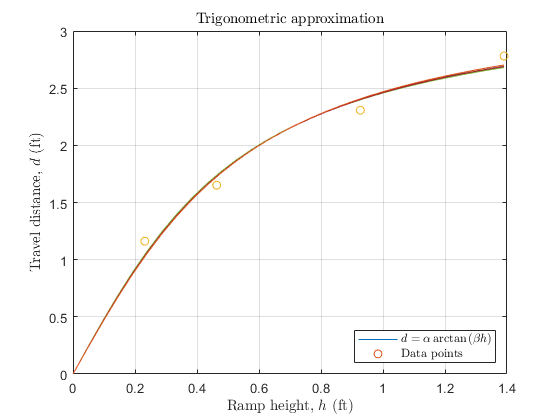

% Store parameters alpha, beta
trig_params = zeros(length(IV), 2);

% Using the fit function
for i = 1:5
    f = strcat('DV', num2str(i));
    ft = fit(IV, eval(f), 'alpha*atan(beta*x)', 'StartPoint', [30, 1]);
    % Amplitude
    trig_params(i, 1) = ft.alpha;
    % Period
    trig_params(i, 2) = ft.beta;
end

% Plotting the arctan models
figure;
h = linspace(0, max(IV), 30);
for i = 1:5
    % Getting the fit parameters
    alpha = trig_params(i, 1);
    beta = trig_params(i, 2);
    % Plotting the arctan function
    d3 = alpha*atan(beta*h);
    plot(h, d3);
    grid on;
    hold on;
    % Plotting the data points
    scatter(IV, DV1);
    f = strcat('DV', num2str(i));
end
legend("$d = \alpha \arctan{(\beta h)}$", "Data points", "interpreter", "latex",  location="southeast");
title("Trigonometric approximation", "interpreter", "latex");
ylabel("Travel distance, $d$ (ft)", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");

#### Polynomial fit

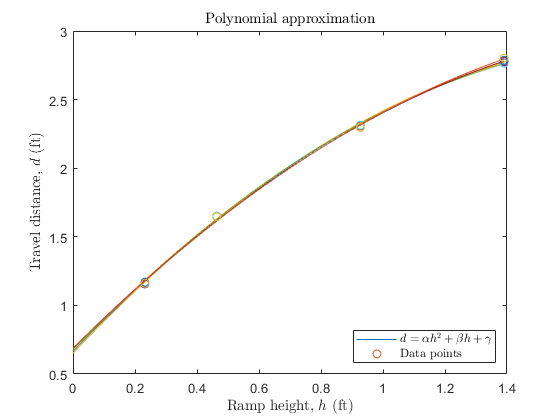

% Store parameters alpha, beta, gamma
poly_params = zeros(length(IV), 3);

% Using the fit function
for i = 1:5
    f = strcat('DV', num2str(i));
    ft = fit(IV, eval(f), 'alpha*x^2 + beta*x + gamma', 'StartPoint', [0,0,1.3]);
    poly_params(i, 1) = ft.alpha;
    poly_params(i, 2) = ft.beta;
    poly_params(i, 3) = ft.gamma;
 end

% Plotting the polynomial models
figure;
h = linspace(0, max(IV), 30);
for i = 1:5
    % Getting the parameters
    alpha = poly_params(i, 1);
    beta = poly_params(i, 2);
    gamma = poly_params(i, 3);
    % Plotting the polynomial fit
    d4 = alpha*h.^2 + beta.*h + gamma;
    plot(h, d4);
    hold on;
    % Plotting the data points
    f = strcat('DV', num2str(i));
    scatter(IV, eval(f));
end
legend("$d = \alpha h^2 + \beta h + \gamma$", "Data points", "interpreter", "latex", location="southeast");
title("Polynomial approximation", "interpreter", "latex");
ylabel("Travel distance, $d$ (ft)", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");

#### Estimating vertical distance $y$

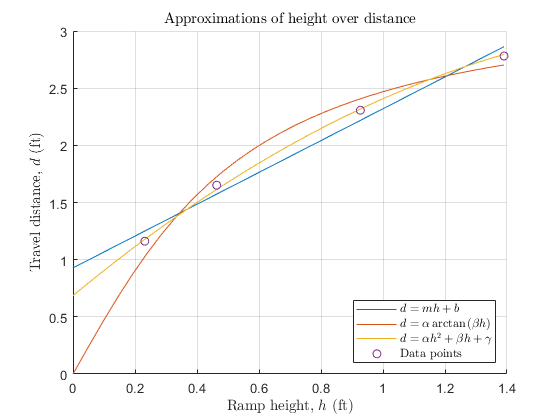

%% Relate fall height h to horizontal travel distance d
% Recall the linear and quadratic fits obtained above
figure;
grid on;
hold on;
plot(h, d2);
plot(h, d3);
plot(h, d4);
scatter(IV, DV1);
title("Approximations of height over distance", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");
ylabel("Travel distance, $d$ (ft)", "interpreter", "latex");
legend("$d=mh+b$", "$d=\alpha \arctan{(\beta h)}$", "$d = \alpha h^2 + \beta h + \gamma$", "Data points", "interpreter", "latex", location="southeast");


fprintf("Fits for P1.10 Table 1.2 data (averaged)...")

Fits for P1.10 Table 1.2 data (averaged)...

fprintf("d = " + mean(linear_params(:, 1)) + "h + " + mean(linear_params(:, 2)))

d = 1.3753h + 0.93918

fprintf("d = " + mean(trig_params(:, 1)) + "arctan(" + mean(trig_params(:, 2)) + "h)")

d = 2.1259arctan(2.2872h)

fprintf("d = " + mean(poly_params(:, 1)) + "h^2 + " + mean(poly_params(:, 2)) + "h + " + mean(poly_params(:, 3)));

d = -0.57718h^2 + 2.3161h + 0.67227

Using the conservation of energy equation:

       $\frac{1}{2}mv_x^2 = mgh$,

we can obtain the horizontal velocity v_x of the ball when it has left the ramp:

   $\Rightarrow v_x = \sqrt{2gh}$.

Using the vertical component of the projectile motion equation:

      
$$y = \frac{1}{2}gt^2,$$$


we can solve for t, the time (in seconds) for the ball to hit the ground:

   $\Rightarrow t=\sqrt{2\frac{y}{g}}$.

Using the horizontal component of the projectile motion equation:

$\;\;\;\;\;\;\;d=v_{x\;} t$,

we can solve for y using the above derivations:

$d=\sqrt{2\textrm{gh}}\sqrt{2\frac{y}{g}}$,

$\;\;=2\sqrt{\textrm{yh}}$,

$\Rightarrow \frac{d^2 }{4}$ = yh. 

Now we can perform a linear fit of $\frac{d^2 }{4}$  versus $h$ to get an estimate for $y$, as such:


$$\frac{d^2 }{4}\approx \alpha \;h\Rightarrow y\approx \alpha \;\textrm{ft}\ldotp$$


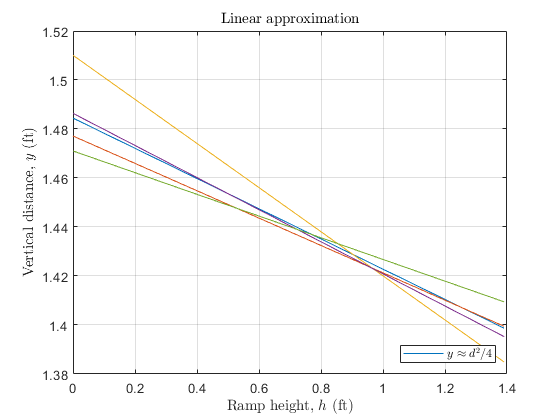

%% Fitting (d^2/4) versus h

% Store parameters alpha, beta
y_params = zeros(length(IV), 2);

% Using the fit function
for i = 1:5
    f = strcat('DV', num2str(i));
    dv = 0.25.*eval(f).^2 ./ IV;
    % Fitting the form of the equation of y
    ft = fit(IV, dv, 'poly1');
    % p1 is the slope
    y_params(i, 1) = ft.p1;
    % p2 is the y-intercept
    y_params(i, 2) = ft.p2;
end

% Plotting the linear models
figure;
h = linspace(0, max(IV), 30);
for i = 1:5
    % Plotting the fit function curve
    alpha = y_params(i, 1);
    beta = y_params(i, 2);
    y = alpha*h + beta;
    plot(h, y);
    grid on;
    hold on;
end
legend("$y \approx d^2/4$", "interpreter", "latex",  location="southeast");
title("Linear approximation", "interpreter", "latex");
ylabel("Vertical distance, $y$ (ft)", "interpreter", "latex");
xlabel("Ramp height, $h$ (ft)", "interpreter", "latex");

%% To otain the estimate of y, we consider the coefficent of d^2/4
fprintf("d^2/4 = " + mean(y(:,1)) + "h")

d^2/4 = 1.471h

fprintf("y is approximately " + mean(y(:, 1)) + " ft.")

y is approximately 1.471 ft.